# Dimensionality reduction

The training examples in "split.mat" contains 31 features:

clear all;
load('split.mat', 'train_examples');

Use Principal Components Analysis to investigate reducing the dimensionality of the resulting feature space.

Marks are available for:

- Applying appropriate pre-processing steps to the data [4 marks]

- Recovering the principal components, and the transformed data [4 marks]

- Taking sensible steps to decide on how many principle components to retain [6 marks]

- Creating the new lower-dimensional dataset [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
%applying z score to the training examples
train_examples

train_examples = 427×31 table
        id        radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    <s

m.mean = mean(train_examples{:,:});
m.std = std(train_examples{:,:});
            for i=1:size(train_examples,1)
				train_examples{i,:} = train_examples{i,:} - m.mean;
                train_examples{i,:} = train_examples{i,:} ./ m.std;
            end
 m.train_examples = train_examples;
 

train_examples = 427×31 table
       id       radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se     smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    

 ms = train_examples{:,:}

ms =    -0.2332   -0.4532   -1.5089   -0.5230   -0.4885   -1.5602   -1.1790   -1.0085   -0.9551   -0.7158   -0.3648   -0.2620    0.4699   -0.3689   -0.3385    1.2486   -0.8464   -0.7950   -0.6144    1.0343    0.3984   -0.6224   -1.5301   -0.7009   -0.5920   -1.6398   -1.1908   -1.1904   -1.3389   -1.0177   -0.7412
   -0.2333   -0.2132   -1.3016   -0.2277   -0.2978   -0.8645   -0.3321   -0.4644   -0.5039   -0.7010   -0.9476   -0.8235   -1.2485   -0.6487   -0.5629   -1.0009   -0.2600   -0.1193   -0.5227   -0.7251   -0.4336   -0.4017   -1.3656   -0.2980   -0.4324   -0.6765    0.0957    0.0624   -0.3352   -0.2671   -0.5833
   -0.2334   -1.4538   -0.0950   -1.3188   -1.1769    0.2622    1.7505    1.3667    0.0339    1.9376    3.4328    0.2739    1.2345    0.5319   -0.3481    1.0482    2.2158    2.1808    2.1659    1.8115    1.5499   -1.2802   -0.3833   -1.1422   -1.0136   -0.4379    0.7670    0.8716    0.0168    0.3898    1.1636
   -0.1626   -0.2952    1.3562   -0.3626   -0.3617   -0.8603  

 [principal_components, data_transformed, ~, ~, explained] = pca(ms)

principal_components =     0.0182   -0.0362    0.0988   -0.0122    0.0047   -0.1651    0.8956   -0.3175   -0.0497    0.2049   -0.0135    0.0800    0.0273    0.0389   -0.0075    0.0199   -0.0025   -0.0484   -0.0090    0.0432   -0.0028   -0.0093   -0.0065    0.0053   -0.0050   -0.0034   -0.0024    0.0030    0.0028   -0.0034   -0.0005
    0.2109   -0.2409   -0.0163   -0.0375   -0.0434    0.0190   -0.0941   -0.1048    0.0676    0.1662    0.0238    0.2094   -0.0002    0.0163    0.0448    0.0353    0.1387   -0.1154    0.0815   -0.2478   -0.1247    0.0166    0.0502    0.2258    0.0516    0.0219   -0.1855    0.0867   -0.2339   -0.1714    0.7032
    0.0983   -0.0645    0.1058    0.6053   -0.0063   -0.0166    0.0153   -0.0783    0.0671   -0.1715   -0.2022    0.0929   -0.3880   -0.1429   -0.0201   -0.1471    0.1763   -0.0205    0.0351   -0.1355    0.0879   -0.4638   -0.0987   -0.1758   -0.0665   -0.0754   -0.0121    0.0271   -0.0003    0.0029    0.0001
    0.2205   -0.2222   -0.0178   -0.0373   -

data_transformed =    -4.0097   -0.2995    2.0384   -1.6528   -0.0916    0.4727   -0.2972    0.5191    1.0597    0.5266    0.2735    0.6502    0.6970   -0.2470   -0.7273   -0.2988    0.1553   -0.1061    0.0805    0.1066    0.2658    0.2137    0.2149    0.0686    0.0912    0.1563   -0.0939    0.0651   -0.0319    0.0074    0.0034
   -2.2568   -0.8900   -1.2828   -1.5597   -1.5101    0.2363   -0.0638   -0.1173    0.0550   -0.0608   -0.1642   -0.4029    0.3813   -0.0892    0.3436   -0.1901   -0.2197   -0.0411    0.0693   -0.1563    0.2142   -0.0449    0.0475   -0.1047    0.0478    0.0538    0.1253    0.1036   -0.0017   -0.0093    0.0097
    1.6919    6.5463    2.0244   -0.2795   -0.9937    0.7312   -0.0070    0.3270   -0.9737   -0.0932   -0.9648   -0.4164   -0.1116   -0.8303   -0.7510    0.9933    0.0606    0.0311   -0.2976    0.0844   -0.0474   -0.0773    0.0323    0.0728   -0.3381    0.1259    0.0358   -0.2526   -0.0304    0.0157    0.0366
   -3.1542   -2.0070    0.2118    1.8112    0.12

explained =    43.2901
   19.1611
    8.2906
    6.3819
    5.3778
    3.7336
    3.4003
    2.0272
    1.4223
    1.3882


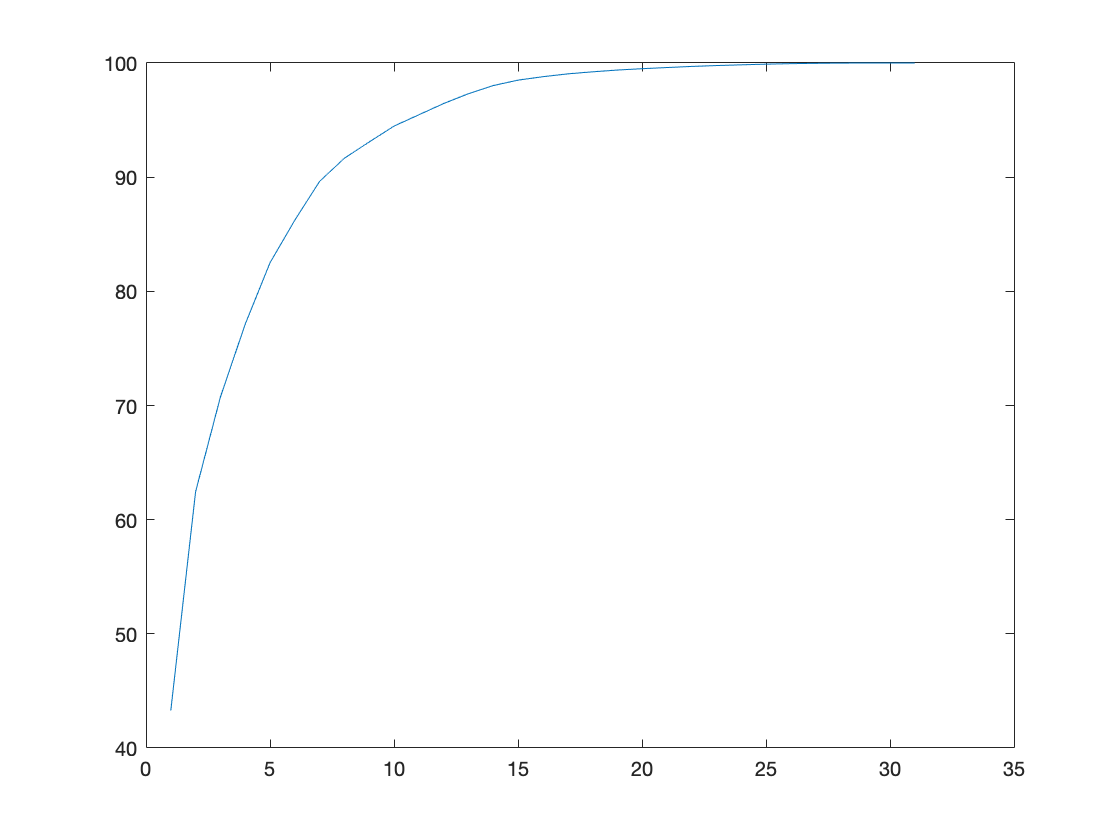

%plotting the graph for the pc's
plot(cumsum(explained));

%I’ll keep the first 15 PCs in order to explain at least 98% of the variance in my training data
data_reduced = data_transformed(:, 1:1:15)

data_reduced =    -4.0097   -0.2995    2.0384   -1.6528   -0.0916    0.4727   -0.2972    0.5191    1.0597    0.5266    0.2735    0.6502    0.6970   -0.2470   -0.7273
   -2.2568   -0.8900   -1.2828   -1.5597   -1.5101    0.2363   -0.0638   -0.1173    0.0550   -0.0608   -0.1642   -0.4029    0.3813   -0.0892    0.3436
    1.6919    6.5463    2.0244   -0.2795   -0.9937    0.7312   -0.0070    0.3270   -0.9737   -0.0932   -0.9648   -0.4164   -0.1116   -0.8303   -0.7510
   -3.1542   -2.0070    0.2118    1.8112    0.1212   -0.3519   -0.2105   -0.2294   -0.2635   -0.6784   -0.4617    0.2755   -0.3175   -0.1110    0.2750
   -0.8637    0.9836   -1.0266   -1.0183    0.5251    1.1585    0.1636   -0.4723    1.0643   -0.2973    0.9147    0.0313    0.1535   -0.0574   -0.1680
   -1.3871    0.1266    1.4652   -1.0578   -2.7269   -0.6340   -0.6221   -0.6741   -0.1152    0.1356   -0.1264   -1.1041    0.5149   -0.2594    0.0187
    2.2148    0.2288    1.0205    1.4038    0.8805   -1.5353   -0.4221   -0.273



 
%train_examples